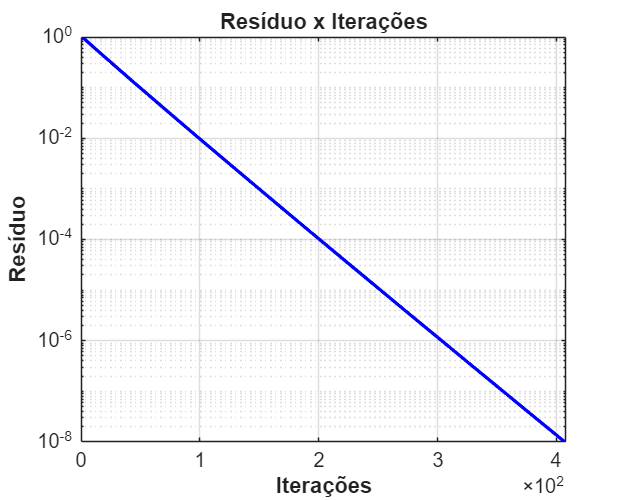

clc; clear; close all;

%% 1. Leitura dos dados
dados = load('norma_iter_chip.dat');
dados_tempo = load('convergencia_passos.dat');
passos      = dados_tempo(:,1);
tempo_vec   = dados_tempo(:,2);
iter_conv   = dados_tempo(:,3);
res_final   = dados_tempo(:,4);

tol = 1e-8;

iteracoes = dados(:, 1);
residuo   = dados(:, 2);

figure('Name', 'Resíduo de Poisson', 'Color', 'w', 'Position', [750, 200, 500, 400]);
semilogy(iteracoes, residuo, 'b-', 'LineWidth', 2);
grid on;

ax = gca; 
set(ax, 'YMinorGrid', 'on', 'FontSize', 12);
ax.XAxis.Exponent = 2;
xlabel('Iterações', 'FontWeight', 'bold');
ylabel('Resíduo', 'FontWeight', 'bold');
title('Resíduo x Iterações', 'FontWeight', 'bold');
% Trava o eixo X do zero até a última iteração
xlim([0 max(iteracoes)]);

% Trava o eixo Y da tolerância exata até o resíduo inicial (máximo)
ylim([tol max(residuo)]);

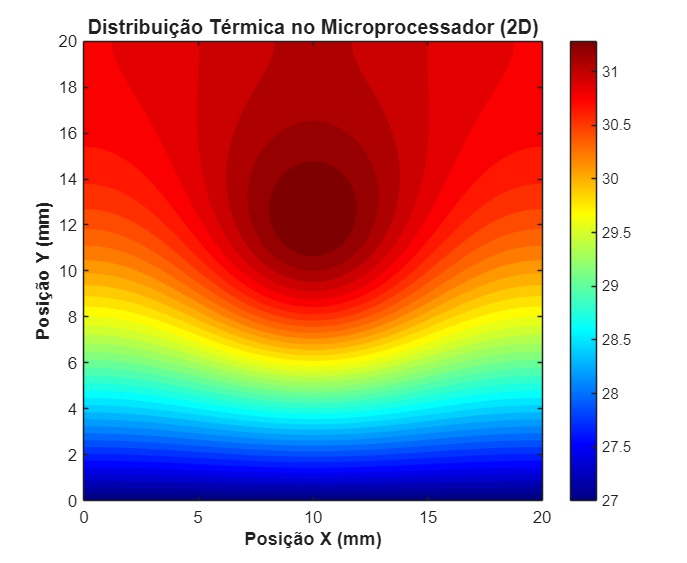

% =========================================================================
% PLOT 1: MAPA DE CALOR E SUPERFÍCIE 3D (ESTADO FINAL)
% =========================================================================

% Parâmetros da malha (Conforme seu parametros.txt)
Nx = 100; Ny = 100;
Lx = 0.02; Ly = 0.02;

% 1. Carregar dados
dados = load('mapa_calor_chip.dat'); 
X = reshape(dados(:, 1), [Nx, Ny])';
Y = reshape(dados(:, 2), [Nx, Ny])';
T = reshape(dados(:, 3), [Nx, Ny])';

% --- Figura 1: Mapa de Calor 2D ---
figure('Name', 'Mapa de Calor do Chip', 'Color', 'w', 'Position', [100, 100, 550, 450]);
contourf(X*1000, Y*1000, T, 40, 'LineColor', 'none'); % Coordenadas em mm
colormap(jet);
colorbar;
xlabel('Posição X (mm)', 'FontWeight', 'bold');
ylabel('Posição Y (mm)', 'FontWeight', 'bold');
title('Distribuição Térmica no Microprocessador (2D)', 'FontSize', 12);
axis equal; axis tight;

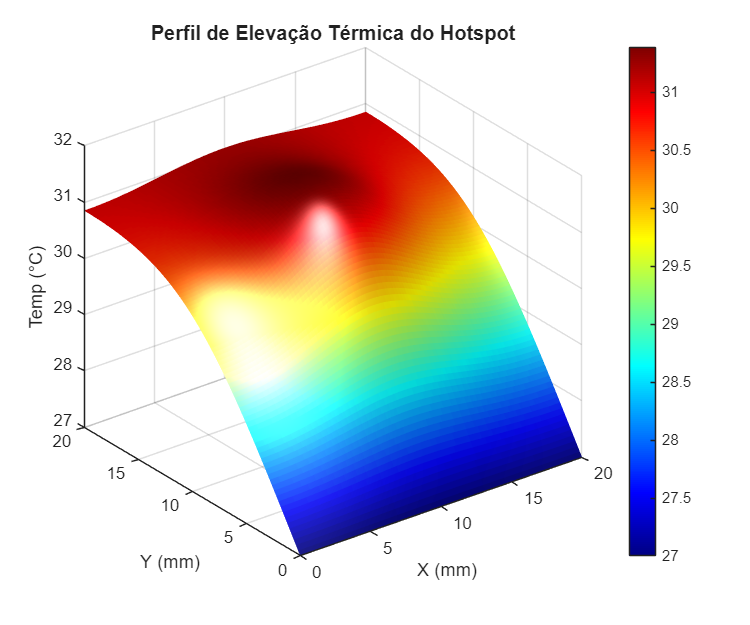


% --- Figura 2: Superfície 3D (Efeito Visual Gaussiano) ---
figure('Name', 'Superfície Térmica 3D', 'Color', 'w', 'Position', [700, 100, 600, 500]);
surf(X*1000, Y*1000, T, 'EdgeColor', 'none');
colormap(jet);
view(3); % Visão 3D
camlight; lighting phong; % Melhora a iluminação
colorbar;
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('Temp (°C)');
title('Perfil de Elevação Térmica do Hotspot', 'FontSize', 12);

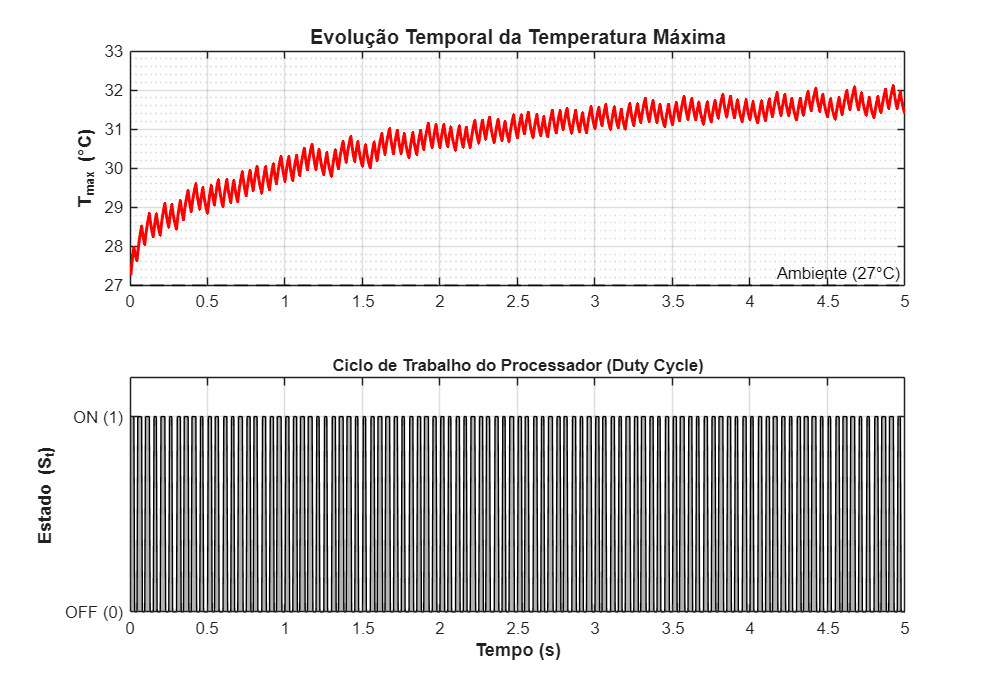

% =========================================================================
% PLOT 2: RESPOSTA TRANSITÓRIA E CICLO DE TRABALHO (DUTY CYCLE)
% =========================================================================

% 1. Carregar dados (n, tempo, Tmax, St)
dados = load('tmax_tempo.dat'); 
tempo = dados(:, 2);
T_max = dados(:, 3);
S_t   = dados(:, 4);

figure('Name', 'Análise Transiente', 'Color', 'w', 'Position', [200, 200, 800, 550]);

% --- Subplot Superior: Temperatura Máxima ---
subplot(2, 1, 1);
plot(tempo, T_max, 'r-', 'LineWidth', 1.8);
hold on;
yline(27, 'k--', 'Ambiente (27°C)', 'LineWidth', 1.2); % Linha de referência T0
grid on; set(gca, 'YMinorGrid', 'on');
ylabel('T_{max} (°C)', 'FontWeight', 'bold');
title('Evolução Temporal da Temperatura Máxima', 'FontSize', 12);
xlim([0 max(tempo)]);

% --- Subplot Inferior: Estado da Carga (S_t) ---
subplot(2, 1, 2);
area(tempo, S_t, 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'k'); % Onda quadrada
grid on;
xlabel('Tempo (s)', 'FontWeight', 'bold');
ylabel('Estado (S_t)', 'FontWeight', 'bold');
yticks([0 1]);
yticklabels({'OFF (0)', 'ON (1)'});
title('Ciclo de Trabalho do Processador (Duty Cycle)', 'FontSize', 10);
xlim([0 max(tempo)]);
ylim([0 1.2]);

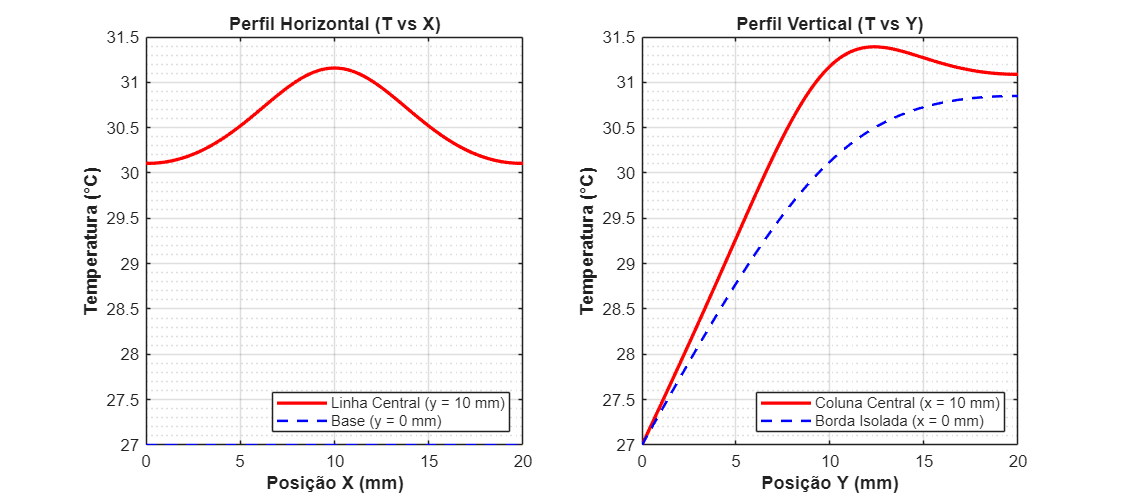

% =========================================================================
% PLOT 3: PERFIS ESPACIAIS NA LINHA CENTRAL (T vs X) e (T vs Y)
% =========================================================================
Nx = 100; Ny = 100;
Lx = 0.02; Ly = 0.02;

% Carrega os dados do estado final
dados = load('mapa_calor_chip.dat'); 
X = reshape(dados(:, 1), [Nx, Ny])';
Y = reshape(dados(:, 2), [Nx, Ny])';
T = reshape(dados(:, 3), [Nx, Ny])';

% Índices centrais e de borda
idx_cx = round(Nx / 2); % Meio do eixo X
idx_cy = round(Ny / 2); % Meio do eixo Y

% --- DADOS PARA O EIXO X ---
x_linha = X(idx_cy, :);     
T_cx_centro = T(idx_cy, :); % Linha passando bem no meio (y = 10mm)
T_cx_borda  = T(1, :);      % Linha na base do chip (y = 0mm)

% --- DADOS PARA O EIXO Y ---
y_coluna = Y(:, idx_cx);
T_cy_centro = T(:, idx_cx); % Coluna passando bem no meio (x = 10mm)
T_cy_borda  = T(:, 1);      % Coluna na borda esquerda isolada (x = 0mm)

figure('Name', 'Perfis Espaciais', 'Color', 'w', 'Position', [150, 200, 900, 400]);

% Gráfico 1: Perfil em X (Horizontal)
subplot(1, 2, 1);
plot(x_linha*1000, T_cx_centro, 'r-', 'LineWidth', 2); hold on;
plot(x_linha*1000, T_cx_borda, 'b--', 'LineWidth', 1.5);
grid on; set(gca, 'YMinorGrid', 'on');
xlabel('Posição X (mm)', 'FontWeight', 'bold');
ylabel('Temperatura (°C)', 'FontWeight', 'bold');
title('Perfil Horizontal (T vs X)', 'FontWeight', 'bold');
legend({'Linha Central (y = 10 mm)', 'Base (y = 0 mm)'}, 'Location', 'southeast');
xlim([0 Lx*1000]);

% Gráfico 2: Perfil em Y (Vertical)
subplot(1, 2, 2);
plot(y_coluna*1000, T_cy_centro, 'r-', 'LineWidth', 2); hold on;
plot(y_coluna*1000, T_cy_borda, 'b--', 'LineWidth', 1.5);
grid on; set(gca, 'YMinorGrid', 'on');
xlabel('Posição Y (mm)', 'FontWeight', 'bold');
ylabel('Temperatura (°C)', 'FontWeight', 'bold');
title('Perfil Vertical (T vs Y)', 'FontWeight', 'bold');
legend({'Coluna Central (x = 10 mm)', 'Borda Isolada (x = 0 mm)'}, 'Location', 'southeast');
xlim([0 Ly*1000]);

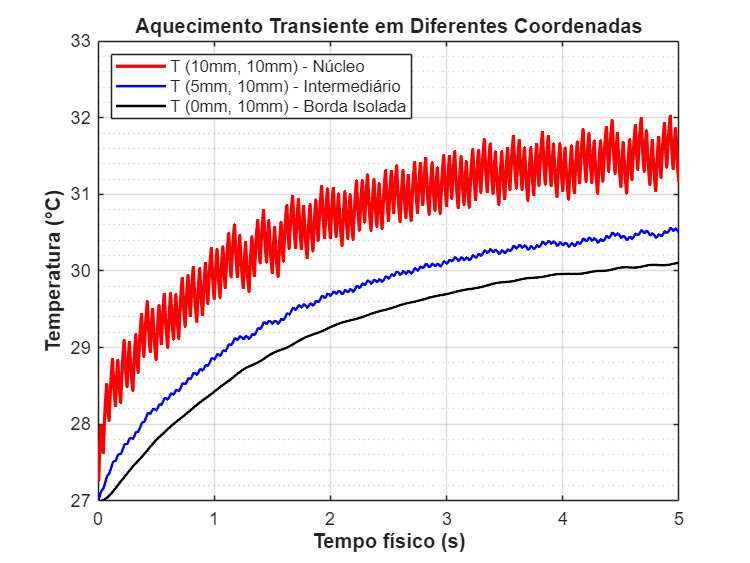

% =========================================================================
% PLOT 4: PERFIL TEMPORAL MULTISSENSOR (Réplica da Figura 9c)
% =========================================================================

% Carrega os dados dos sensores
dados = load('sensores_tempo.dat'); 
tempo = dados(:, 1);
T_centro = dados(:, 2);
T_interm = dados(:, 3);
T_borda  = dados(:, 4);

figure('Name', 'Sensores de Temperatura', 'Color', 'w', 'Position', [300, 250, 600, 450]);

% Plota as três linhas de sensores (Inspirado nas cores do seu PDF)
plot(tempo, T_centro, 'r-', 'LineWidth', 2); hold on;
plot(tempo, T_interm, 'b-', 'LineWidth', 1.5);
plot(tempo, T_borda, 'k-', 'LineWidth', 1.5);

grid on; set(gca, 'YMinorGrid', 'on', 'FontSize', 11);
xlabel('Tempo físico (s)', 'FontWeight', 'bold');
ylabel('Temperatura (°C)', 'FontWeight', 'bold');
title('Aquecimento Transiente em Diferentes Coordenadas', 'FontWeight', 'bold');

% Legenda com as coordenadas exatas
legend({'T (10mm, 10mm) - Núcleo', ...
        'T (5mm, 10mm) - Intermediário', ...
        'T (0mm, 10mm) - Borda Isolada'}, ...
        'Location', 'northwest', 'FontSize', 10);

xlim([0 max(tempo)]);